% This m-file executes simulation and generates figures for the
% analysis of the state of emergency placed in Chiba in the paper
% "Covid-19 and Output in Japan" by Daisuke Fujii and Taisuke
% Nakata

clear variables
close all
home = '/Users/masam/Dropbox/fujii_nakata/Website/Codes/';
cd(home);
%====================== Program parameter values ======================%
figure_save = 1;    % 0 = figures won't be saved, 1 = they will be saved
data_save = 1;      % save back data
iPC=1;              % 1 if PC, 0 if Mac (or "home=pwd" does not work)
% in the "Figure" folder
fs = 16;            % common font size for many figures
xlim_tradeoff = [3,4];
%======================================================================%

PrefVector = {'Tokyo','Osaka','Kanagawa','Saitama','Chiba','Fukuoka','Aichi','Hyogo'};
%PrefVector = {'Tokyo'};
th_on_vector = [1500,500,600,400,350,300,300,250]*7;
GDP_vector = [106,40,36,24,22,18,38,20]*100;
for pindex = 8
    %====================== Model parameter values ======================%
    % pref = 'Tokyo';        % prefecture to be analyzed
    pref = PrefVector(pindex);
    prefGDP = GDP_vector(pindex);
    gamma = 7/5;          % recovery rate from Covid
    k = 2;                 % exponent of (1-h*alpha)
    hconstant = 1;         % 0 = without intercept, 1 = with intercept for h regression
    SimPeriod = 52;        % simulation period in weeks
    TargetAlpha = 0.1:0.1:8;      % values of alpha we simulate results
    AlphaVals = [1.5,0.85*(1.5+3)/2,3];   % benchmark alpha we plot time-series figures
    VacStartDate = "Apr-01";             % time until the start of vaccination process
    
    VacDuration = 12;       % time until vaccination pace reaches its steady pace
    RetroPeriod = 17;      % retroactive periods used to estimate gamma and delta
    
    % th_off = 3500;         % threshold to remove the state of emergency (daily new infected persons in Tokyo = 500)
    target_duration = 8;
    wl = [1,2];            % Results as of these weeks ago
    %====================================================================%
    
    %--- Import data ---%
    % Covid data are recorded at weekly frequencies (Mon-Sun)
    % The first week start on January 20 (Mon), 2020
    if iPC==1
        covid = importdata([home '\Covid_weekly.csv']);  % Import weekly Covid data by prefecture
    else
        covid = importdata([home 'Covid_weekly.csv']);  % Import weekly Covid data by prefecture
    end
    Data = covid.data(strcmp(covid.textdata(2:end,1),pref),:);
    % Columns: 1 = date, 2 = new positive, 3 = death, 4 = mobility, 5 = GDP, 6 = population
    dateD = Data(:,1) + 21916;
    N = Data(:,2);
    dD = Data(:,3);
    M = Data(:,4);
    GDP = Data(:,5);
    POP = Data(:,6);
    Tdata= size(Data,1);    % Data period in weeks
    POP0 = POP(1);          % initial population
    xtick1 = 1:13:Tdata;
    dateJP = string(datetime(dateD,'ConvertFrom','excel','Format','M月dd日'));
    dateEN = string(datetime(dateD,'ConvertFrom','excel','Format','MMM-dd'));
    Month = string(datetime(dateD,'ConvertFrom','excel','Format','MMM-yy'));
    SimDate = dateD(end)+7:7:dateD(end)+7*SimPeriod;
    SimDateEN = string(datetime(SimDate,'ConvertFrom','excel','Format','MMM-dd'));
    %--- Create Month-Week labels ---%
    dateP = dateD(end)+7:7:dateD(end)+7*(SimPeriod+1);
    date = [dateD;dateP'];
    MonthNumber = month(datetime(date,'ConvertFrom','excel'));
    WeekNumber = zeros(length(MonthNumber),1);
    WeekNumber(1:2) = [3;4];
    for i = 3:length(WeekNumber)
        if MonthNumber(i)~=MonthNumber(i-1)
            WeekNumber(i) = 1;
        else
        WeekNumber(i) = WeekNumber(i-1) + 1;
        end
    end
    MonthWeekJP = strings([length(MonthNumber),1]);
    MonthWeekEN = strings([length(MonthNumber),1]);
    for i = 1:length(MonthNumber)
        MonthWeekJP(i) = [char(string(MonthNumber(i))) '月第' char(string((WeekNumber(i)))) '週'];
        MonthWeekEN(i) = [char(string(datetime(date(i),'ConvertFrom','excel','Format','MMM'))) '-' char(string((WeekNumber(i)))) 'w'];
    end

    M = 1+0.01*M;
    TdataGDP = Tdata-sum(isnan(GDP));
    RetroH = TdataGDP-4;
    VacStart = find(SimDateEN == "Apr-01");
    End2020 = find(dateEN == "Jan-07");
    
    
    VacPace = (POP0/125710000)*0.8*(3000000/2);  % number of vaccinations per week
 
    
    %--- Constructing the reference level of output ---%
    potentialGDP = zeros(52*3,1);
    potentialGDP(1) = (100/(1.0122))*(1.0063^(1/12));
    for i = 2:length(potentialGDP)
        if i <= 13
            potentialGDP(i) = potentialGDP(i-1)*(1.0063^(1/52));
        elseif i <= 52
            potentialGDP(i) = potentialGDP(i-1)*(1.0021^(1/52));
        elseif i <= 104
            potentialGDP(i) = potentialGDP(i-1)*(1.0024^(1/52));
        elseif i <= 156
            potentialGDP(i) = potentialGDP(i-1)*(1.0021^(1/52));
        end
    end
    % gapGDP = zeros(length(potentialGDP),1);
    % gapGDP(1) = 0.0166;
    % for i = 2:length(gapGDP)
    %     gapGDP(i) = gapGDP(i-1)*(0.975^(12/52));
    % end
    referenceGDP = potentialGDP.*(1+0.0166);
    referenceGDP(1:2) = [];
    
    
    %--- Impute alpha (regress alpha on M)---%
    Malt=M;
    Malt(50)=0.5*(Malt(49)+Malt(51));
    alpha = (1 - GDP(1:TdataGDP)./referenceGDP(1:TdataGDP));   % output loss in percentage
    X = M(TdataGDP-17:TdataGDP);
    Y = alpha(TdataGDP-17:TdataGDP);
    XC = [ones(length(X),1), X];
    s = (XC'*XC)\XC'*Y;         % OLS estimate of h with constant
    reg = XC*s;
    r = Y - reg;
    SSE = sum(r.^2);
    eps_p = zeros(Tdata-TdataGDP,1);
    eps_p(1) = r(end);
    for i = 1:Tdata-TdataGDP-1
        eps_p(i+1) = 1*eps_p(i);
    end
    alpha_pred = s(1)+s(2)*Malt(TdataGDP+1:Tdata)+eps_p;
    
    alpha = [alpha;alpha_pred];
    
    %
    % %--- Plot mobility data ---%
    % figure(2)
    % yyaxis left
    % plot(M,'k','LineWidth',1.5)
    % ylabel('Mobility')
    % yyaxis right
    % plot(GDP,'b-.','LineWidth',1.5)
    % ylabel('GDP')
    % xlim([1 Tdata])
    % xticks(xtick1)
    % xticklabels(Month(xtick1))
    % legend('Mobility (left axis)','GDP (right axis)','FontSize',16,'Location','north');
    % ax = gca;
    % ax.YAxis(1).Color = 'k';
    % ax.YAxis(2).Color = 'b';
    % ax.YAxis(1).FontSize = fs;
    % ax.YAxis(2).FontSize = fs;
    % ax.XAxis.FontSize = fs;
    
    
    %--- Regress mobility on alpha to estimate the elasticity h ---%
    Y = M(4:TdataGDP);
    X = alpha(4:TdataGDP);
    if hconstant == 0
        Y = Y - 1;
        h_all = (X'*X)\X'*Y;              % OLS estimate of h
        reg = X*h_all;
        r = Y - reg;                % r is the residuals, which is the observed minus fitted values
        SSE = sum(r.^2);            % SSE is the sum of squared errors
        MSE=SSE/(length(Y)-1);      % mean squared error
        h_all_se=sqrt(MSE/sum(X.^2));   % standard error of h
    elseif hconstant == 1
        XC = [ones(length(X),1), X];
        h_all = (XC'*XC)\XC'*Y;         % OLS estimate of h with constant
        reg = XC*h_all;
        r = Y - reg;
        SSE = sum(r.^2);
        MSE=SSE/(length(Y)-1);      % mean squared error
        h_all_se = zeros(2,1);
        h_all_se(1)=sqrt(MSE/sum(XC(:,1).^2));   % standard error of h
        h_all_se(2)=sqrt(MSE/sum(XC(:,2).^2));
    end
    
    Y = M(TdataGDP-RetroH:TdataGDP);
    X = alpha(TdataGDP-RetroH:TdataGDP);
    if hconstant == 0
        Y = Y - 1;
        h = (X'*X)\X'*Y;              % OLS estimate of h
        reg = X*h;
        r = Y - reg;                % r is the residuals, which is the observed minus fitted values
        SSE = sum(r.^2);            % SSE is the sum of squared errors
        MSE=SSE/(length(Y)-1);      % mean squared error
        h_se=sqrt(MSE/sum(X.^2));   % standard error of h
    elseif hconstant == 1
        XC = [ones(length(X),1), X];
        h = (XC'*XC)\XC'*Y;         % OLS estimate of h with constant
        reg = XC*h;
        r = Y - reg;
        SSE = sum(r.^2);
        MSE=SSE/(length(Y)-1);      % mean squared error
        h_se = zeros(2,1);
        h_se(1)=sqrt(MSE/sum(XC(:,1).^2));   % standard error of h
        h_se(2)=sqrt(MSE/sum(XC(:,2).^2));
    end
    
    
    
    
    % figure(100)
    % if hconstant == 0
    %     scatter(X,Y,60,'filled')
    %     hold on
    %     plot(X,reg,'LineWidth',1.5)
    % elseif hconstant == 1
    %     scatter(XC(:,2),Y,60,'filled')
    %     hold on
    %     plot(XC(:,2),reg,'LineWidth',1.5)
    % end
    % xlabel('Output loss (%)');
    % ylabel('Mobility');
    % aa = gca;
    % aa.YAxis.FontSize = fs;
    % aa.XAxis.FontSize = fs;
    % hold off
    
    
    
    %--- Compute the history of S, I, R, D in the data period ---%
    S = zeros(Tdata+1,1);
    I = zeros(Tdata+1,1);
    R = zeros(Tdata+1,1);
    D = zeros(Tdata+1,1);
    S(1)=POP0;
    for i = 1:Tdata
        S(i+1)=S(i)-N(i);
        I(i+1)=I(i)+N(i)-gamma*I(i)-dD(i);
        R(i+1)=R(i)+gamma*I(i);
        D(i+1)=D(i)+dD(i);
        if i > TdataGDP
            GDP(i) = referenceGDP(i)*(1-alpha(i));
        end
    end
    
    %--- Compute the history of time-varying parameters ---%
    
    delta = (D(2:Tdata+1)-D(1:Tdata))./I(1:Tdata);                              % death rate
    beta_tilde = -POP0*((S(2:Tdata+1)-S(1:Tdata))./(S(1:Tdata).*I(1:Tdata)));   % overall infection rate
    ERN = (S(1:end-1)/POP0).*beta_tilde./(gamma+delta);                                        % effective reproduction number
    if hconstant == 0
        beta = beta_tilde./(1+h_all*alpha).^k;                                      % raw infection rate
    elseif hconstant == 1
        %     beta = beta_tilde./(h(1)+h(2)*alpha).^k;
        beta = beta_tilde./(1+(h_all(2)/h_all(1))*alpha).^k;
    end
    AverageAlpha2020 = 100*mean([alpha(1);alpha(2);alpha]);
    
    
    %--- Plot varabiles in the data period ---%
    % figure(1)
    % plot(N,'k','LineWidth',2)
    % xlim([1 Tdata])
    % xticks(xtick1)
    % yticks([0 10000 20000 30000 40000])
    % xticklabels(Month(xtick1))
    % xtickangle(45)
    % ax = gca;
    % ax.YAxis.FontSize = 16;
    % ax.XAxis.FontSize = 16;
    % ax.YAxis.Exponent = 0;
    % ytickformat('%,6.0f')
    
    
    VarList = ["S","I","R","D","N","GDP"];
    VarName = ["S","I","R","D","N","Y"];
    %
    % for i = 1:length(VarList)
    %     figure(4)
    %     subplot(2,3,i)
    %     plot(eval(VarList(i)),'k','LineWidth',2)
    %     xlim([1 Tdata])
    %     title(VarName(i),'FontWeight','normal')
    %     xticks(xtick1)
    %     xticklabels(Month(xtick1))
    %     xtickangle(45)
    %     if i == 5
    %         ax = gca;
    %         ax.YAxis.Exponent = 0;
    %         ytickformat('%,6.0f')
    %     end
    %     if i == length(VarList)
    %         hold on
    %         plot(referenceGDP,'k--','LineWidth',2)
    %     end
    % end
    
    
    %--- Plot parameters in the data period ---%
    ParamList = ["alpha","ERN","beta","delta"];
    ParamName = ["$\alpha$ (decline in Y)","Effective reproduction number",...
        "$\beta$ (raw infection rate)","$\delta$ (death rate)"];
    % for i = 1:4
    %     figure(3)
    %     subplot(2,2,i)
    %     plot(eval(ParamList(i)),'k','LineWidth',2)
    %     xlim([1 Tdata])
    %     title(ParamName(i),'Interpreter','latex','FontSize',14,'FontWeight','normal')
    %     xticks(xtick1)
    %     xticklabels(Month(xtick1))
    %     xtickangle(45)
    %     if i == 2
    %         ylim([0 2.5]);
    %         yline(1);
    %     end
    %     if i == 3
    %         ylim([0 5]);
    %     end
    %     if i == 4
    %         ylim([0 0.1]);
    %     end
    % end
    
    
    
    %%%%%%%%%%%%%%%%% Projection starts here %%%%%%%%%%%%%%%%%
    
    %--- Construct time series of parameters ---%
%     InitialValues = [S(end),I(end),R(end),D(end)];
%     beta_sample = beta(end-RetroPeriod+1:end);
%     delta_sample = delta(end-RetroPeriod+1:end);
%     beta_average = mean(beta_sample);
%     delta_average = mean(delta_sample);
%     delta_ss = delta_average*(0.09/1.27);
%     betaT = beta_average*ones(SimPeriod,1);
%     deltaT = delta_average*ones(SimPeriod,1);
%     deltaT(VacStart+3:VacStart+3+9+13) = delta_average:(delta_ss-delta_average)/22:delta_ss;
%     deltaT(VacStart+3+9+13+1:end) = delta_ss;
%     gammaT = gamma*ones(SimPeriod,1);
%     % V = zeros(SimPeriod,1);
%     % V(VacStart:end) = VacPace;
%     V = zeros(SimPeriod,1);
%     V(VacStart-1:VacStart+VacDuration-1) = 0:VacPace/VacDuration:VacPace;
%     V(VacStart+VacDuration:end) = VacPace;
    CumD = zeros(1,length(TargetAlpha));
    AverageAlpha = zeros(1,length(TargetAlpha));
    LagResults = zeros(2,length(TargetAlpha),length(wl));
    ParamList2 = ["alpha2","ERN2","beta2","delta2"];
    
    
    %--- Sensitivity parameters ---%
%     BetaVals = beta_average*[1.05, 1, 0.95];
%     KVals = [1.5, 2, 2.5];
%     HVals = [0.8, 1, 1.2];
%     
%     VacStartVals = [16, 12, 20];
%     VacPaceVals = [0.5*VacPace, VacPace, 2*VacPace];
%     FrontLoadingVals = [0.5, 1, 1.5];
%     SA = zeros(3,length(TargetAlpha),4);    % matrix to contain the results of sensitivity analysis
    AlphaIndexVariables = zeros(SimPeriod,6,length(AlphaVals));    % matrix to contain the projected variables for certain alpha values
    %
    % %--- Simulation for different alpha values ---%
    % for i = 1:length(TargetAlpha)

## Baseline projection %%%

    %     alphaT = zeros(SimPeriod,1);
    %     alphaT(1:26) = flip(0:0.01*TargetAlpha(i)*4/(26-1):(0.01*TargetAlpha(i)*4))';
    %     [CumD(i),AverageAlpha(i),SimData,SimN]=Covid_projection(InitialValues,alphaT,betaT,gammaT,deltaT,V,h,k,POP0,hconstant);

## Results from previous weeks %%%

    %     for j = 1:length(wl)
    %         wlag = wl(j);
    %         VacStartL = VacStart + wlag;
    %         VL = zeros(SimPeriod,1);
    %         VL(VacStartL-1:VacStartL+VacDuration-1) = 0:VacPace/VacDuration:VacPace;
    %         VL(VacStartL+VacDuration:end) = VacPace;
    %         InitialValuesL = [S(end-wlag),I(end-wlag),R(end-wlag),D(end-wlag)];
    %         betaL = mean(beta(end-RetroPeriod+1-wlag:end-wlag))*ones(SimPeriod,1);
    %         %         deltaL = mean(delta(end-RetroPeriod+1-wlag:end-wlag))*ones(SimPeriod,1);
    %         delta_averageL = mean(delta(end-RetroPeriod+1-wlag:end-wlag));
    %         delta_ssL = delta_averageL*(0.09/1.27);
    %         deltaL = delta_averageL*ones(SimPeriod,1);
    %         deltaL(VacStart+3:VacStart+3+9+13) = delta_averageL:(delta_ssL-delta_averageL)/22:delta_ssL;
    %         deltaL(VacStart+3+9+13+1:end) = delta_ssL;
    %         [LagResults(1,i,j),LagResults(2,i,j)]=Covid_projection(InitialValuesL,alphaT,betaL,gammaT,deltaL,VL,h,k,POP0,hconstant);
    %     end

## Beta sensitivity %%%

    %     for j = 1:length(BetaVals)
    %         betaS = BetaVals(j)*ones(SimPeriod,1);
    %         [SA(j,i,1)]=Covid_projection(InitialValues,alphaT,betaS,gammaT,deltaT,V,h,k,POP0,hconstant);
    %     end

## h sensitivity %%%

    %     for j = 1:length(HVals)
    %         if hconstant == 0
    %             HS = HVals(j);
    %         elseif hconstant == 1
    %             HS = h;
    %             HS(2) = h(2)*HVals(j);
    %         end
    %         [SA(j,i,2)]=Covid_projection(InitialValues,alphaT,betaT,gammaT,deltaT,V,HS,k,POP0,hconstant);
    %     end

## k sensitivity %%%

    %     for j = 1:length(KVals)
    %         kS = KVals(j);
    %         [SA(j,i,3)]=Covid_projection(InitialValues,alphaT,betaT,gammaT,deltaT,V,h,kS,POP0,hconstant);
    %     end

## VacPace sensitivity %%%

    %     for j = 1:length(VacPaceVals)
    %         VacPaceS = VacPaceVals(j);
    %         VS = zeros(SimPeriod,1);
    %         VS(VacStart-1:VacStart+VacDuration-1) = 0:VacPaceS/VacDuration:VacPaceS;
    %         VS(VacStart+VacDuration:end) = VacPaceS;
    %         [SA(j,i,4)]=Covid_projection(InitialValues,alphaT,betaT,gammaT,deltaT,VS,h,k,POP0,hconstant);
    %     end
    % end

## Time series figures (variables and parameters) %%%

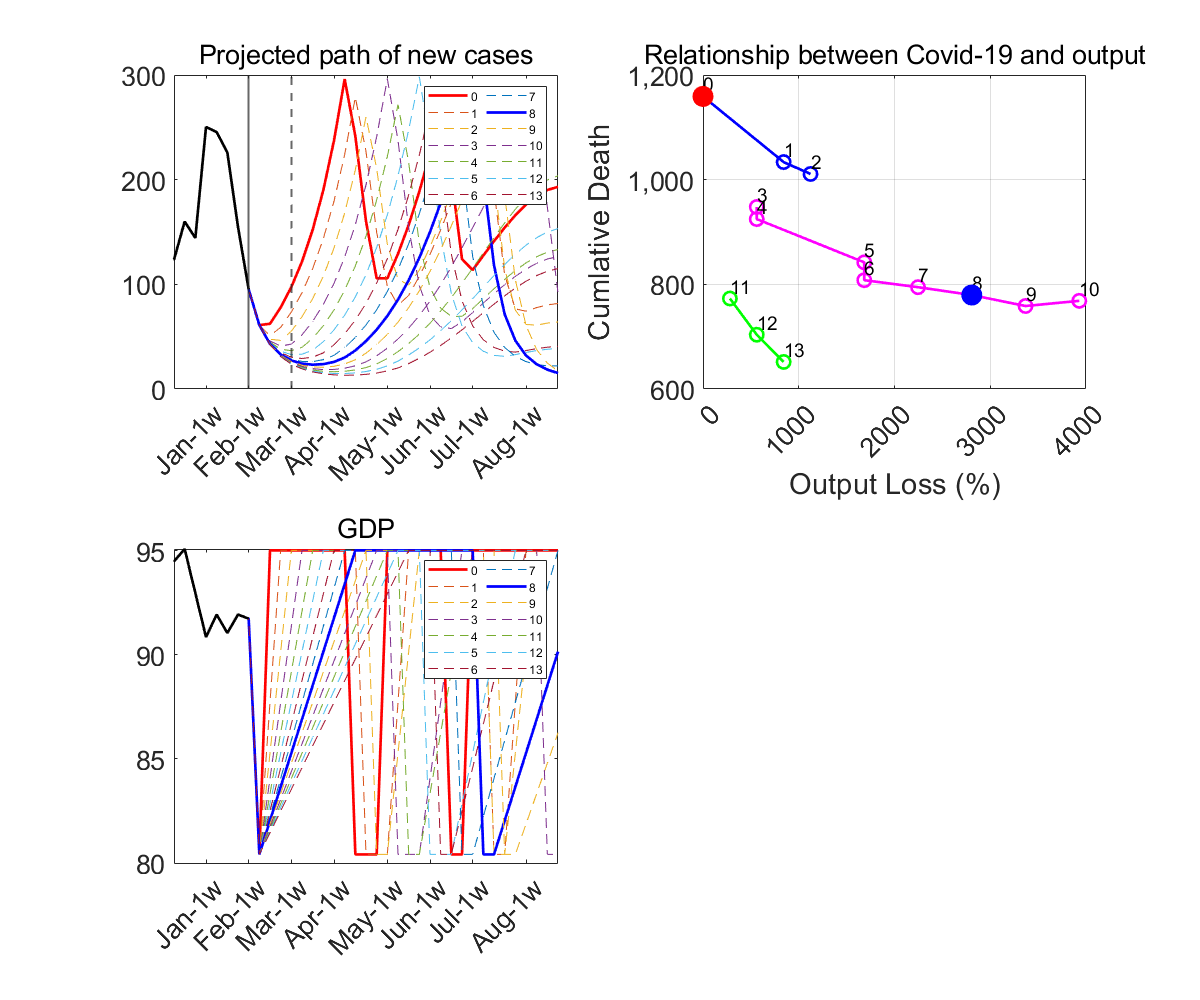

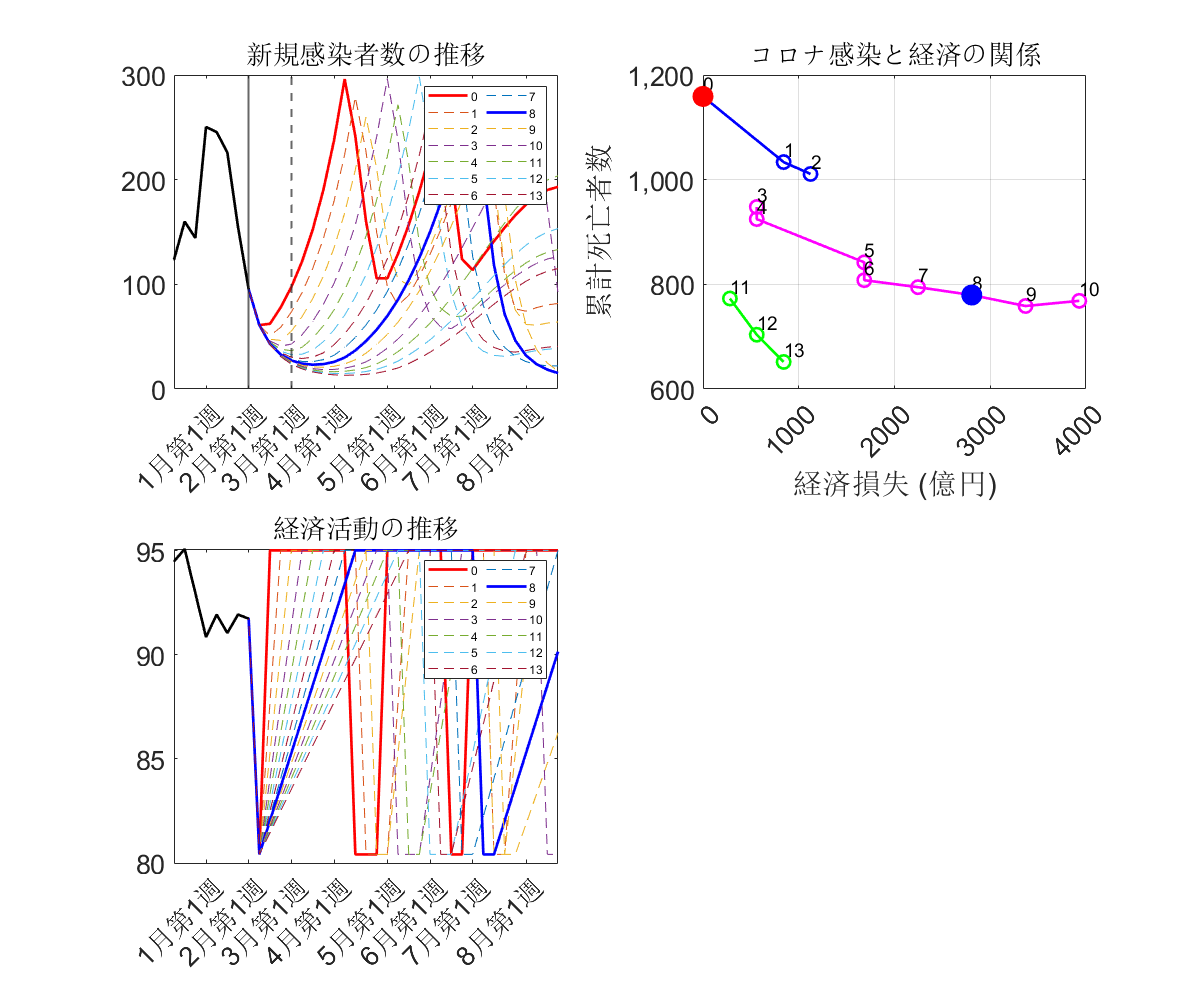

    % for i = 1:length(AlphaVals)
    %     alphaT = zeros(SimPeriod,1);
    %     alphaT(1:26) = flip(0:0.01*AlphaVals(i)*4/(26-1):(0.01*AlphaVals(i)*4))';
    %     SimGDP = referenceGDP(Tdata+1:Tdata+length(alphaT)).*(1-alphaT);
    %     [CD,AA,SimData,SimN]=Covid_projection(InitialValues,alphaT,betaT,gammaT,deltaT,V,h,k,POP0,hconstant);
    %     AlphaIndexVariables(:,:,i) = [SimData(1:end-1,:),SimN,SimGDP];
    % end
    %
    % Past = [N,GDP,ERN,zeros(Tdata,1)];
    % VarList2 = ["N","GDP","ERN","V"];
    % VarName2 = ["N","Y","Effective reproduction number","Newly vaccinated persons"];
    % for i = 1:length(AlphaVals)
    %     %     alphaT = flip(0:0.01*AlphaVals(i)*2/(SimPeriod-1):(0.01*AlphaVals(i)*2))';
    %     alphaT = zeros(SimPeriod,1);
    %     alphaT(1:26) = flip(0:0.01*AlphaVals(i)*4/(26-1):(0.01*AlphaVals(i)*4))';
    %     %     alphaT = 0.01*AlphaVals(i)*ones(SimPeriod,1);
    %     if hconstant == 0
    %         ERNT = (AlphaIndexVariables(:,1,i)/POP0).*(((1+h*alphaT).^k).*betaT)./(gammaT+deltaT);
    %     elseif hconstant == 1
    %         ERNT = (AlphaIndexVariables(:,1,i)/POP0).*(((1+(h(2)/h(1))*alphaT).^k).*betaT)./(gammaT+deltaT);
    %     end
    %     ProjectedData = [AlphaIndexVariables(:,5,i),AlphaIndexVariables(:,6,i),ERNT,V];
    %     CombinedData = [Past;ProjectedData];
    %     figure(5)
    %     for j = 1:length(VarList2)
    %         subplot(2,2,j)
    %         plot(CombinedData(:,j),'k','LineWidth',2)
    %         xlim([1 Tdata+SimPeriod])
    %         title(VarName2(j),'FontWeight','normal')
    %         xline(Tdata);
    %         xticks([1 27 53 79 98])
    %         xticklabels( {'Jan-20','Jul-20','Jan-21','Jul-21','Dec-21'} )
    %         xtickangle(45)
    %         if j == 1
    %             yticks([2e4 4e4 6e4 8e4 10e4 12e4]);
    %             ax = gca;
    %             ax.YAxis.Exponent = 0;
    %             ytickformat('%,6.0f')
    %         end
    %         if j == 3
    %             ylim([0 3]);
    %             yline(1);
    %         end
    %         if j == 4
    %             yticks([5e5 10e5 15e5 20e5 25e5]);
    %             yticklabels({'0.5M','1M','1.5M','2M','2.5M'});
    %         end
    %         hold on
    %     end
    %
    %     alpha2 = [alpha;alphaT];
    %     beta2 = [beta;betaT];
    %     if hconstant == 0
    %         beta_tildeT = betaT.*(1+h*alphaT).^k;                                      % raw infection rate
    %     elseif hconstant == 1
    %         %     beta_tildeT = betaT.*(h(1)+h(2)*alpha).^k;
    %         beta_tildeT = betaT.*(1+(h(2)/h(1))*alphaT).^k;
    %     end
    %     beta_tilde2 = [beta_tilde;beta_tildeT];
    %     ERN2 = [ERN;ERNT];
    %     delta2 = [delta;deltaT];
    %     V2 = [zeros(Tdata,1);V];
    %     figure(101)
    %     %set(gcf,'Position',[100,100,800,500])
    %     for j = 1:length(ParamList2)
    %         subplot(2,2,j)
    %         plot(eval(ParamList2(j)),'k','LineWidth',2)
    %         xlim([1 Tdata+SimPeriod])
    %         title(ParamName(j),'Interpreter','latex','FontSize',11,'FontWeight','normal')
    %         xline(Tdata);
    %         xticks([1 27 53 79 98])
    %         xticklabels( {'Jan-20','Jul-20','Jan-21','Jul-21','Dec-21'} )
    %         xtickangle(45)
    %         if j == 2
    %             ylim([0,2])
    %         end
    %         if j == 3
    %             ylim([0,5])
    %         end
    %         if j == 4
    %             ylim([0,0.1])
    %         end
    %         hold on
    %     end
    % end
    %
    %
    %
    % %--- Trade-off figure (baseline) ---%
    % figure(102)
    % plot(100*AverageAlpha,CumD,'k','LineWidth',2)
    % xlabel('Output Loss (%)','FontSize',fs)
    % ylabel('Cumlative Deaths','FontSize',fs)
    % xlim(xlim_tradeoff);
    % yline(D(End2020),'r--','LineWidth',1.5);
    % grid on
    % ax = gca;
    % ax.YAxis.FontSize = fs;
    % ax.XAxis.FontSize = fs;
    % ax.YAxis.Exponent = 0;
    % ytickformat('%,6.0f')
    %
    % %--- Trade-off figure (lag) ---%
    % figure(8)
    % plot(100*AverageAlpha,CumD,'k','LineWidth',2,'DisplayName','baseline')
    % legend('baseline')
    % hold on
    % for i = 1:length(wl)
    %     wlag = wl(i);
    %     if wlag == 1
    %         plot(100*LagResults(2,:,i),LagResults(1,:,i),'LineWidth',2,'DisplayName',sprintf('%.0f week ago',wlag))
    %     else
    %         plot(100*LagResults(2,:,i),LagResults(1,:,i),'LineWidth',2,'DisplayName',sprintf('%.0f weeks ago',wlag))
    %     end
    %     hold on
    % end
    % hold off
    % xlabel('Output Loss (%)','FontSize',fs)
    % ylabel('Cumlative Deaths','FontSize',fs)
    % xlim(xlim_tradeoff);
    % ylim([0 60000]);
    % xline(AverageAlpha2020,'LineWidth',1.5,'HandleVisibility','off');
    % text(3.5,100000,{'Output loss';'      in 2020'},'FontSize',16);
    % ax = gca;
    % ax.YAxis.FontSize = fs;
    % ax.XAxis.FontSize = fs;
    % ax.YAxis.Exponent = 0;
    % ytickformat('%,6.0f')
    % lgd = legend;
    % lgd.NumColumns = 1;
    % lgd.FontSize = 15;
    % %lgd.Location = 'north';
    % grid on
    
    
    
    
    %%%%%%%%%%%%%%%%% Projection starts here %%%%%%%%%%%%%%%%%
    alpha_off = mean(alpha(Month == "Sep-20" | Month == "Oct-20"  | Month == "Nov-20")); % output loss without the state of emergency
    InitialValues = [S(end),I(end),R(end),D(end)];
 
    %--- Construct time series of parameters ---%
    beta_sample = beta(end-RetroPeriod+1:end);
    betaT = mean(beta_sample)*ones(SimPeriod,1);
    delta_sample = delta(end-RetroPeriod+1:end);
    delta_average = mean(delta_sample);
    delta_ss = delta_average*(0.09/1.27);
    deltaT = delta_average*ones(SimPeriod,1);
    deltaT(VacStart+4:VacStart+4+8+18) = delta_average:(delta_ss-delta_average)/26:delta_ss;
    deltaT(VacStart+4+8+18+1:end) = delta_ss;
    gammaT = gamma*ones(SimPeriod,1);
    V = zeros(SimPeriod,1);
    V(VacStart-1:VacStart+VacDuration-1) = 0:VacPace/VacDuration:VacPace;
    V(VacStart+VacDuration:end) = VacPace;
   
    %--- Projection for different th_off values ---%
    th_on = th_on_vector(pindex);         % threshold to place the state of emergency (daily new infected persons in Tokyo = 2000)
%     if pindex == 1
%         TH = (100:50:1000)*7;
%         TH_index = [500,250]*7;
%     elseif pindex == 2 || pindex == 3
%         TH = (20:10:300)*7;
%         TH_index = [150,50]*7;
%     elseif pindex == 4 || pindex == 5
%         TH = (20:10:300)*7;
%         TH_index = [100,50]*7;
%     end
    
    TH = 0:13;
    TH_index = [0,8];
    DM = zeros(1,length(TH));
    AlphaM = zeros(1,length(TH));
    AlphaPath = zeros(SimPeriod,length(TH));
    NPath = zeros(SimPeriod,length(TH));
    
    % SimAlpha = 0.089;
    % SimERN = (S(end)/POP0).*(((1+(h(2)/h(1))*SimAlpha).^k).*betaT(1))./(gammaT(1)+deltaT(1));
    
    %--- Plot scenarios ---%
    %ERN_on = [0.88,0.95,0.7];
    ERN_on = 0.77;
    altA = (((ERN_on*(POP0/S(end))*((gammaT(1)+deltaT(1))/betaT(1))).^(1/k))-1)*(h(1)/h(2));
  
    % % ERNCheck = (S(end)/POP0).*(((1+(h(2)/h(1))*altA).^k).*betaT(1))./(gammaT(1)+deltaT(1));
 
    for l = 1:2
        for y = 1:length(altA)
            alpha_on = altA(y);
            if l == 1
                figure(11+y)
            elseif l == 2
                figure((11+y)*10+1)
            end
            %set(gcf,'Position',[100,100,1200,500])
            set(gcf,'Position',[100,100,1200,1000])
            subplot(2,2,1)
            for i = 1:length(TH)
                [DM(i),AlphaM(i),AlphaPath(:,i),SimData,NPath(:,i)] = Covid_projection_control_gradual(InitialValues,altA,alpha_off,th_on,140*7,betaT,gammaT,deltaT,V,h_all,k,POP0,hconstant,TH(i));
                
                if TH(i) == TH_index(1)
                    plot([N;NPath(:,i)]/7,'-r','LineWidth',2,'DisplayName',sprintf('%.0f',TH(i)))
                    if y == 1
                        red = [N(end-7:end);NPath(:,i)];
                    end
                elseif TH(i) == TH_index(2)
                    plot([N;NPath(:,i)]/7,'-b','LineWidth',2,'DisplayName',sprintf('%.0f',TH(i)))
                    if y == 1
                        blue = [N(end-7:end);NPath(:,i)];
                    end
                else
                    plot([N;NPath(:,i)]/7,'--','LineWidth',0.3,'DisplayName',sprintf('%.0f',TH(i)))
                end
                hold on
            end
            plot(N/7,'k','LineWidth',2,'HandleVisibility','off')
            xline(Tdata,'LineWidth',1.5,'HandleVisibility','off');
            xline(Tdata+find(SimDateEN == "Mar-04"),'--','LineWidth',1.5,'HandleVisibility','off');
            ax = gca;
            ax.YAxis.FontSize = 20;
            ax.XAxis.FontSize = 20;
            ax.YAxis.Exponent = 0;
            ytickformat('%,6.0f')
            %ylabel('Number of new cases per week','FontSize',20)
            %xticks([-3,1,5,9,14,18,22,27]+Tdata)
            xticks(find(WeekNumber==1))
            if l == 1
                title('Projected path of new cases','FontSize',20,'FontWeight','normal')
                xticklabels(MonthWeekEN(WeekNumber==1))
            elseif l == 2
                title('新規感染者数の推移','FontSize',20,'FontWeight','normal')
                xticklabels(MonthWeekJP(WeekNumber==1))
                %xticklabels({'1月第1週','2月第1週','3月第1週','4月第1週','5月第1週','6月第1週','7月第1週','8月第1週'})
            end
            lgd = legend;
            lgd.NumColumns = 2;
            xtickangle(45)
            xlim([Tdata-7 Tdata+29])
            % xticks([1 14 27 40 52])
            % xticklabels(dateP([1 14 27 40 52]))
            xtickangle(45)
            
            %--- Record how many times on and off are triggered ---%
            waves = zeros(1,length(TH));
            for i = 1:length(TH)
                svec = zeros(SimPeriod-1,1);
                for t = 1:SimPeriod-1
                    svec(t) = AlphaPath(t+1,i)-AlphaPath(t,i);
                end
                waves(i) = nnz(svec);
            end
            
            %--- Number of cumulative deaths ---%
            if y == 1
                minAlpha = min(AlphaM)*100;
            end
            AlphaM = AlphaM*100;
            AlphaM = (AlphaM - minAlpha)*prefGDP;
            if y == 1
                AD = [AlphaM',DM'];
%                 AD1 = [AlphaM(waves==1)',DM(waves==1)'];
%                 AD2 = [AlphaM(waves==3)',DM(waves==3)'];
%                 SOE = zeros(1,length(waves));
%                 SOE(waves==3) = 1;
            end
            subplot(2,2,2)
            
            
            
            % The value of alpha changes each period during the gradual
            % release. Therefore, the method that uses waves for
            % differenciating the colors of plots in the second figure does
            % not work.
%             plot(AlphaM(waves==1),DM(waves==1),'-go','LineWidth',2,'MarkerSize',10)
%             hold on
%             plot(AlphaM(waves==3),DM(waves==3),'-mo','LineWidth',2,'MarkerSize',10)
%             hold on
%             plot(AlphaM(waves==5),DM(waves==5),'-bo','LineWidth',2,'MarkerSize',10)
%             hold on

%             plot(AlphaM(1:6),DM(1:6),'-mo','LineWidth',2,'MarkerSize',10);
%             hold on
%             plot(AlphaM(7:end),DM(7:end),'-go','LineWidth',2,'MarkerSize',10);
% %             scatter(AlphaM,DM,250);
%             hold on 

            plot(AlphaM(1:3),DM(1:3),'-bo','LineWidth',2,'MarkerSize',10);
            hold on
            plot(AlphaM(4:11),DM(4:11),'-mo','LineWidth',2,'MarkerSize',10);
%             scatter(AlphaM,DM,250);
            hold on 
            plot(AlphaM(12:end),DM(12:end),'-go','LineWidth',2,'MarkerSize',10)
            hold on
            text(AlphaM,DM,string(TH),'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',14);
            hold on
%             plot(AlphaM(waves==1),DM(waves==1),'-go','LineWidth',2,'MarkerSize',10)
%             hold on
%             plot(AlphaM(waves==3),DM(waves==3),'-mo','LineWidth',2,'MarkerSize',10)
%             hold on
%             plot(AlphaM(waves==5),DM(waves==5),'-bo','LineWidth',2,'MarkerSize',10)
%             hold on
%             text(AlphaM(1),DM(1),string(TH(1)),'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',14)
%             for i = 2:length(AlphaM)
%                 if AlphaM(i)~=AlphaM(i-1) && DM(i)~=DM(i-1)
%                     text(AlphaM(i),DM(i),string(TH(i)),'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',14)
% %                 elseif AlphaM(i)==AlphaM(i-1) && DM(i)==DM(i-1) && AlphaM(i)~=AlphaM(i-2) && DM(i)~=DM(i-2)
% %                     text(AlphaM(i),DM(i),string(TH(i)/7),'VerticalAlignment','top','HorizontalAlignment','left','FontSize',14)
% %                 elseif AlphaM(i)==AlphaM(i-1) && DM(i)==DM(i-1) && AlphaM(i)==AlphaM(i-2) && DM(i)==DM(i-2) && AlphaM(i)~=AlphaM(i-3) && DM(i)~=DM(i-3)
% %                     text(AlphaM(i),DM(i),string(TH(i)/7),'VerticalAlignment','bottom','HorizontalAlignment','right','FontSize',14)
% %                 elseif AlphaM(i)==AlphaM(i-1) && DM(i)==DM(i-1) && AlphaM(i)==AlphaM(i-2) && DM(i)==DM(i-2)&& AlphaM(i)==AlphaM(i-3) && DM(i)==DM(i-3)
% %                     text(AlphaM(i),DM(i),string(TH(i)/7),'VerticalAlignment','top','HorizontalAlignment','right','FontSize',14)
%                 end
%                 hold on
%             end
            %         text(AlphaM,DM,string(TH/7),'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',14)
            %         hold on
%             text(AlphaM(TH==TH_index(1)),DM(TH==TH_index(1)),string(TH(TH==TH_index(1))/7),'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',14)
%             hold on
%             text(AlphaM(TH==TH_index(2)),DM(TH==TH_index(2)),string(TH(TH==TH_index(1))/7),'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',14)
%             hold on
            scatter(AlphaM(TH==TH_index(1)),DM(TH==TH_index(1)),250,'red','filled');
            hold on
            scatter(AlphaM(TH==TH_index(2)),DM(TH==TH_index(2)),250,'blue','filled');
            
            if l == 1
                xlabel('Output Loss (%)','FontSize',20)
                ylabel('Cumlative Death','FontSize',20)
                title('Relationship between Covid-19 and output','FontSize',20,'FontWeight','normal')
            elseif l == 2
                xlabel('経済損失 (億円)','FontSize',20)
                ylabel('累計死亡者数','FontSize',20)
                title('コロナ感染と経済の関係','FontSize',20,'FontWeight','normal')
            end
            xtickangle(45)
            grid on
            ax = gca;
            ax.YAxis.FontSize = 20;
            ax.XAxis.FontSize = 20;
            ax.YAxis.Exponent = 0;
            ax.XAxis.Exponent = 0;
            ytickformat('%,6.0f')
            
            subplot(2,2,3)
            for i = 1:length(TH)
                if TH(i) == TH_index(1)
                    plot((1-[alpha;AlphaPath(:,i)])*100,'-r','LineWidth',2,'DisplayName',sprintf('%.0f',TH(i)))
                     if y == 1
                        redalpha = (1-[alpha(end-7:end);AlphaPath(:,i)])*100;
                    end
                elseif TH(i) == TH_index(2)
                   plot((1-[alpha;AlphaPath(:,i)])*100,'-b','LineWidth',2,'DisplayName',sprintf('%.0f',TH(i)))
                    if y == 1
                        bluealpha = (1-[alpha(end-7:end);AlphaPath(:,i)])*100;
                    end
                else
                    plot((1-[alpha;AlphaPath(:,i)])*100,'--','LineWidth',0.3,'DisplayName',sprintf('%.0f',TH(i)))
                end
                hold on
            end
            plot((1-alpha)*100,'k','LineWidth',2,'HandleVisibility','off')
            %ylabel('Number of new cases per week','FontSize',20)
            %xticks([-3,1,5,9,14,18,22,27]+Tdata)
            xticks(find(WeekNumber==1))
            if l == 1
                title('GDP','FontSize',20,'FontWeight','normal')
                xticklabels(MonthWeekEN(WeekNumber==1))
            elseif l == 2
                title('経済活動の推移','FontSize',20,'FontWeight','normal')
                xticklabels(MonthWeekJP(WeekNumber==1))
                %xticklabels({'1月第1週','2月第1週','3月第1週','4月第1週','5月第1週','6月第1週','7月第1週','8月第1週'})
            end
            lgd = legend;
            lgd.NumColumns = 2;
            xtickangle(45)
            xlim([Tdata-7 Tdata+29])
            ax = gca;
             ax.YAxis.FontSize = 20;
            ax.XAxis.FontSize = 20;
            ax.YAxis.Exponent = 0;
            ytickformat('%,6.0f')
           
            
            
            %     %--- Number of new infections ---%
            %     NM = sum(NPath,1)+sum(N);
            %     subplot(1,2,2)
            %     plot(AlphaM(waves==1),NM(waves==1),'-bo','LineWidth',1.5,'MarkerSize',10)
            %     hold on
            %     plot(AlphaM(waves==3),NM(waves==3),'-go','LineWidth',1.5,'MarkerSize',10)
            %     hold on
            %     plot(AlphaM(waves==5),NM(waves==5),'-mo','LineWidth',1.5,'MarkerSize',10)
            %     hold on
            %     text(AlphaM,NM,string(TH/7),'VerticalAlignment','bottom','HorizontalAlignment','left')
            %     hold on
            %     scatter(AlphaM(TH==500*7),NM(TH==500*7),80,'red','filled');
            %     xlabel('Output Loss (%)','FontSize',20)
            %     ylabel('Cumlative number of infected people','FontSize',20)
            %     title('Relationsihp between Covid-19 and output','FontSize',20,'FontWeight','normal')
            %     grid on
            %     ax = gca;
            %     ax.YAxis.FontSize = 20;
            %     ax.XAxis.FontSize = 20;
            %     ax.YAxis.Exponent = 0;
            %     ytickformat('%,6.0f')
        end
    end
    
    % %--- Combine three scenarios ---%
    % for l = 1:2
    % for y = 1:length(altA)
    %     alpha_on = altA(y);
    %     if l == 1
    %     figure(15)
    %     elseif l == 2
    %         figure(151)
    %     end
    %     set(gcf,'Position',[100,100,1200,500])
    %     subplot(1,2,1)
    %     for i = 1:length(TH)
    %         [DM(i),AlphaM(i),AlphaPath(:,i),SimData,NPath(:,i)] = Covid_projection_control(InitialValues,alpha_on,alpha_off,th_on,TH(i),betaT,gammaT,deltaT,V,h,k,POP0,hconstant);
    %         if sum(TH(i)==TH_index)==1
    %             plot(NPath(:,i),'-r','LineWidth',2,'DisplayName',sprintf('%.0f',TH(i)/7))
    %         else
    %             plot(NPath(:,i),'--','LineWidth',0.3,'DisplayName',sprintf('%.0f',TH(i)/7))
    %         end
    %         hold on
    %     end
    %     ax = gca;
    %     ax.YAxis.FontSize = 20;
    %     ax.XAxis.FontSize = 20;
    %     ax.YAxis.Exponent = 0;
    %     ytickformat('%,6.0f')
    %     %ylabel('Number of new cases per week','FontSize',20)
    %     xticks([1 9 17 25 33 41 49])
    %     if l == 1
    %     title('Projected path of new cases','FontSize',20,'FontWeight','normal')
    %     xticklabels(dateP([1 9 17 25 33 41 49]))
    %     elseif l == 2
    %         title('?????????','FontSize',20,'FontWeight','normal')
    %     xticklabels({'1?','3?','5?','7?','9?'})
    %     end
    %         lgd = legend;
    %         lgd.NumColumns = 2;
    %     xlim([1 SimPeriod])
    %     xtickangle(45)
    %
    %     %--- Record how many times on and off are triggered ---%
    %     waves = zeros(1,length(TH));
    %     for i = 1:length(TH)
    %         svec = zeros(SimPeriod-1,1);
    %         for t = 1:SimPeriod-1
    %             svec(t) = AlphaPath(t+1,i)-AlphaPath(t,i);
    %         end
    %         waves(i) = nnz(svec);
    %     end
    %     %--- Number of cumulative deaths ---%
    %     AlphaM = AlphaM*100;
    %     subplot(1,2,2)
    %     plot(AlphaM(waves==1),DM(waves==1),'-bo','LineWidth',1.5,'MarkerSize',10)
    %     hold on
    %     plot(AlphaM(waves==3),DM(waves==3),'-go','LineWidth',1.5,'MarkerSize',10)
    %     hold on
    %     plot(AlphaM(waves==5),DM(waves==5),'-mo','LineWidth',1.5,'MarkerSize',10)
    %     hold on
    %     text(AlphaM,DM,string(TH/7),'VerticalAlignment','bottom','HorizontalAlignment','left')
    %     hold on
    %     scatter(AlphaM(TH==500*7),DM(TH==500*7),80,'red','filled');
    %     if l == 1
    %     xlabel('Output Loss (%)','FontSize',20)
    %     ylabel('Cumlative Death','FontSize',20)
    %     title('Relationsihp between Covid-19 and output','FontSize',20,'FontWeight','normal')
    %     elseif l == 2
    %          xlabel('???? (%)','FontSize',20)
    %     ylabel('??????','FontSize',20)
    %     title('???????????','FontSize',20,'FontWeight','normal')
    %     end
    %     grid on
    %     ax = gca;
    %     ax.YAxis.FontSize = 20;
    %     ax.XAxis.FontSize = 20;
    %     ax.YAxis.Exponent = 0;
    %     ytickformat('%,6.0f')
    % end
    % end
    % %--- Three vaccination scenarios ---%
    % altV = [0.5, 1, 2];
    % alpha_on = 0.074;
    % for y = 1:length(altV)
    %     VacPaceAlt = altV(y)*VacPace;
    %     V = zeros(SimPeriod,1);
    %     V(VacStart-1:VacStart+3) = 0:VacPaceAlt/4:VacPaceAlt;
    %     V(VacStart+4:end) = VacPaceAlt;
    %     figure(16)
    %     set(gcf,'Position',[100,100,1200,500])
    %     subplot(1,2,1)
    %     for i = 1:length(TH)
    %         [DM(i),AlphaM(i),AlphaPath(:,i),SimData,NPath(:,i)] = Covid_projection_control(InitialValues,alpha_on,alpha_off,th_on,TH(i),betaT,gammaT,deltaT,V,h,k,POP0,hconstant);
    %         if sum(TH(i)==TH_index)==1
    %             plot(NPath(:,i),'-r','LineWidth',2,'DisplayName',sprintf('%.0f',TH(i)/7))
    %         else
    %             plot(NPath(:,i),'--','LineWidth',0.3,'DisplayName',sprintf('%.0f',TH(i)/7))
    %         end
    %         hold on
    %     end
    %     ax = gca;
    %     ax.YAxis.FontSize = 20;
    %     ax.XAxis.FontSize = 20;
    %     ax.YAxis.Exponent = 0;
    %     ytickformat('%,6.0f')
    %     ylabel('Number of new cases per week','FontSize',20)
    %     title('Projected path of new cases','FontSize',20,'FontWeight','normal')
    %     xticks([1 9 17 25 33 41 49])
    %     xticklabels(dateP([1 9 17 25 33 41 49]))
    %     xlim([1 SimPeriod])
    %     xtickangle(45)
    %
    %     %--- Record how many times on and off are triggered ---%
    %     waves = zeros(1,length(TH));
    %     for i = 1:length(TH)
    %         svec = zeros(SimPeriod-1,1);
    %         for t = 1:SimPeriod-1
    %             svec(t) = AlphaPath(t+1,i)-AlphaPath(t,i);
    %         end
    %         waves(i) = nnz(svec);
    %     end
    %     %--- Number of cumulative deaths ---%
    %     AlphaM = AlphaM*100;
    %     subplot(1,2,2)
    %     plot(AlphaM(waves==1),DM(waves==1),'-bo','LineWidth',1.5,'MarkerSize',10)
    %     hold on
    %     plot(AlphaM(waves==3),DM(waves==3),'-go','LineWidth',1.5,'MarkerSize',10)
    %     hold on
    %     plot(AlphaM(waves==5),DM(waves==5),'-mo','LineWidth',1.5,'MarkerSize',10)
    %     hold on
    %     text(AlphaM,DM,string(TH/7),'VerticalAlignment','bottom','HorizontalAlignment','left')
    %     hold on
    %     scatter(AlphaM(TH==500*7),DM(TH==500*7),80,'red','filled');
    %     xlabel('Output Loss (%)','FontSize',20)
    %     ylabel('Cumlative Death','FontSize',20)
    %     title('Relationsihp between Covid-19 and output','FontSize',20,'FontWeight','normal')
    %     grid on
    %     ax = gca;
    %     ax.YAxis.FontSize = 20;
    %     ax.XAxis.FontSize = 20;
    %     ax.YAxis.Exponent = 0;
    %     ytickformat('%,6.0f')
    % end
    
    %--- Save data ---%
    if data_save == 1
        TN = table(MonthWeekJP(Tdata-7:end-1),round(red/7),round(redalpha,1),round(blue/7),round(bluealpha,1));
        TAD = table([round(AD),TH']);
        writetable(TN,[home 'Figures/' char(pref) '/BackData_Gradual' char(pref) '_' char(datetime('today','Format','yyyMMdd')) '.xls'],'Sheet','新規感染者数（1日平均）');
        writetable(TAD,[home 'Figures/' char(pref) '/BackData_Gradual' char(pref) '_' char(datetime('today','Format','yyyMMdd')) '.xls'],'Sheet','経済損失と死亡者数');
    end
        
    %--- Save figures ---%
    if figure_save == 1
        if iPC==1
            saveas(figure(12),[home '\Figures\' char(pref) '\BaselineDeclineGradual.png']);
            saveas(figure(121),[home '\Figures\' char(pref) '\BaselineDeclineGradual_jp.png']);
%             saveas(figure(13),[home '\Figures\' char(pref) '\GradualDecline.png']);
%             saveas(figure(131),[home '\Figures\' char(pref) '\GradualDecline_jp.png']);
%             saveas(figure(14),[home '\Figures\' char(pref) '\RapidDecline.png']);
%             saveas(figure(141),[home '\Figures\' char(pref) '\RapidDecline_jp.png']);
        else
            saveas(figure(12),[home 'Figures/' char(pref) '/BaselineDeclineGradual.png']);
            saveas(figure(121),[home 'Figures/' char(pref) '/BaselineDeclineGradual_jp.png']);
%             saveas(figure(13),[home 'Figures/' char(pref) '/GradualDecline.png']);
%             saveas(figure(131),[home 'Figures/' char(pref) '/GradualDecline_jp.png']);
%             saveas(figure(14),[home 'Figures/' char(pref) '/RapidDecline.png']);
%             saveas(figure(141),[home 'Figures/' char(pref) '/RapidDecline_jp.png']);
            %     saveas(figure(14),[home 'Figures/Tokyo/GradualDecline.png']);
            %     saveas(figure(15),[home 'Figures/Tokyo/ThreeScenariosDecline.png']);
            %     saveas(figure(16),[home 'Figures/Tokyo/ThreeVaccinationsDecline.png']);
        end
    end
    %close all
end